clear;
% Parameters
g = 9.8;       % Gravity
m_c = 1.0;     % Mass of the cart
m_p = 0.1;     % Mass of the pole
l = 0.5;       % Length of the pole

% State Space matrices
A = [0, 1, 0, 0;
     0, 0, (-m_p*g/(m_c+m_p))*(1/(4/3 - m_p/(m_c+m_p))), 0;
     0, 0, 0, 1;
     0, 0, (g)/(l*(4/3 - m_p/(m_c+m_p))), 0];

B = [0;
     1/(m_c+m_p)*(1 + l*m_p/(l*(4/3 - m_p/(m_c+m_p))));
     0;
     (-1/(l*(4/3 - m_p/(m_c+m_p))))*(1/(m_c+m_p))];

C = [1, 0, 0, 0;
     0, 0, 1, 0];

D = 0;

% Open Loop system
sys = ss(A, B, C, D)

sys =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0        0  -0.7171        0
   x3        0        0        0        1
   x4        0        0    15.78        0
 
  B = 
           u1
   x1       0
   x2  0.9823
   x3       0
   x4  -1.463
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


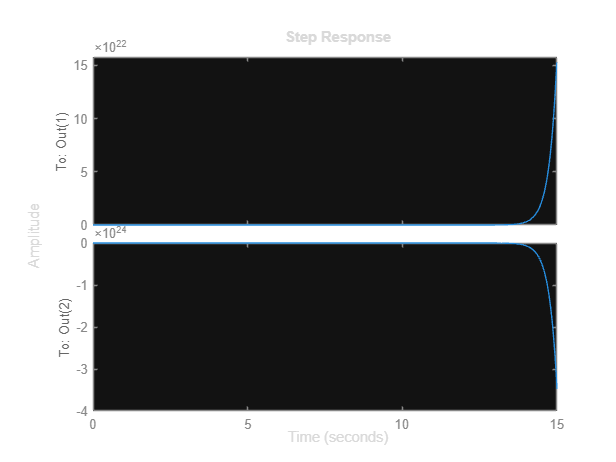

step(sys)

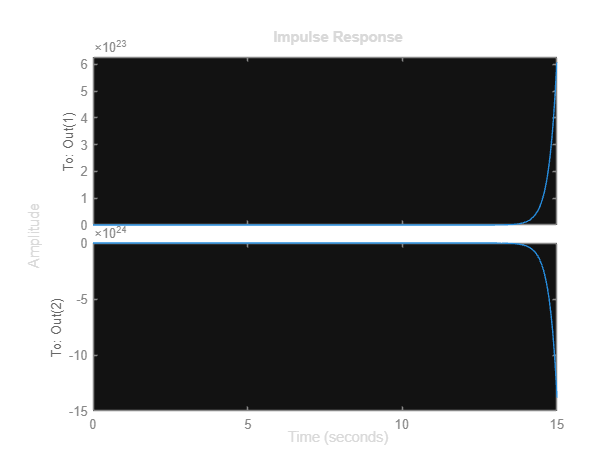

impulse(sys)



% LQR

Q = diag([1,1,1,1]);
R = 1;

K = lqr(sys, Q, R);

A_cl = (A-B*K);
eig(A_cl)

ans =   -4.7749 + 0.0000i
  -3.3207 + 0.0000i
  -0.8145 + 0.4977i
  -0.8145 - 0.4977i


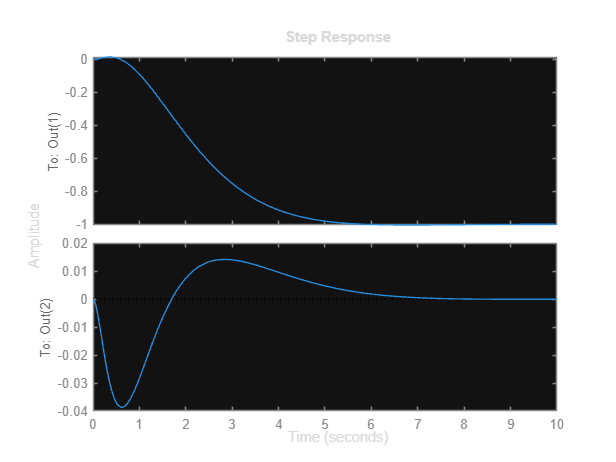


% Closed Loop system
sys_cl = ss(A_cl, B, C, D);
step(sys_cl)

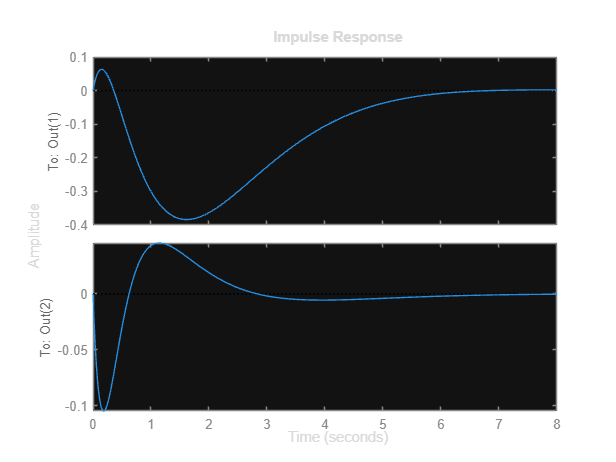

impulse(sys_cl)